# Well-conditioned problems

t = [3.4935 4.2853 5.1374 5.8181 6.8632 8.1841]';

x = [6 10.1333 14.2667 18.4000 22.5333 26.6667]';

## No.1

### a). Find the least squares solutions for the model parameters t_o and s2

exp_val = 0; % expected value
sig = 0.1; % standard deviation

% model
m = length(t);

G = [ones(m,1) x]; % matrix G
M_L2 = inv(G'*G)*G'*t; % least square solution

t_o = M_L2(1) % to

t_o = 2.0323

s_2 = M_L2(2) % s2

s_2 = 0.2203

### Plot the data and the fitted model on the same graph, and the residuals on the second graph.

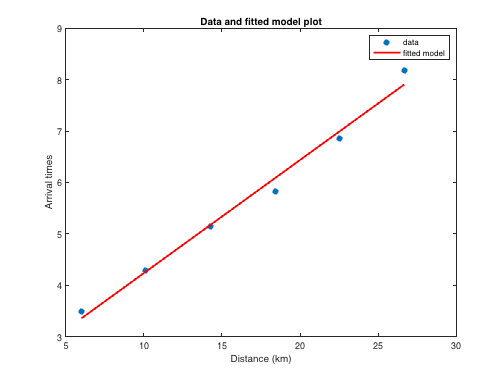

% fitted model
T = zeros(m,1);
for i =1:m
    T(i) = t_o + s_2*x(i);
end

% residuls
GM = G*M_L2;
r = t - GM;

%plot
figure(1)
plot(x,t,'.','MarkerSize',20)
hold on
plot(x,T,'r',LineWidth=2)
legend('data','fitted model')
ylabel('Arrival times')
xlabel('Distance (km)')
title('Data and fitted model plot')

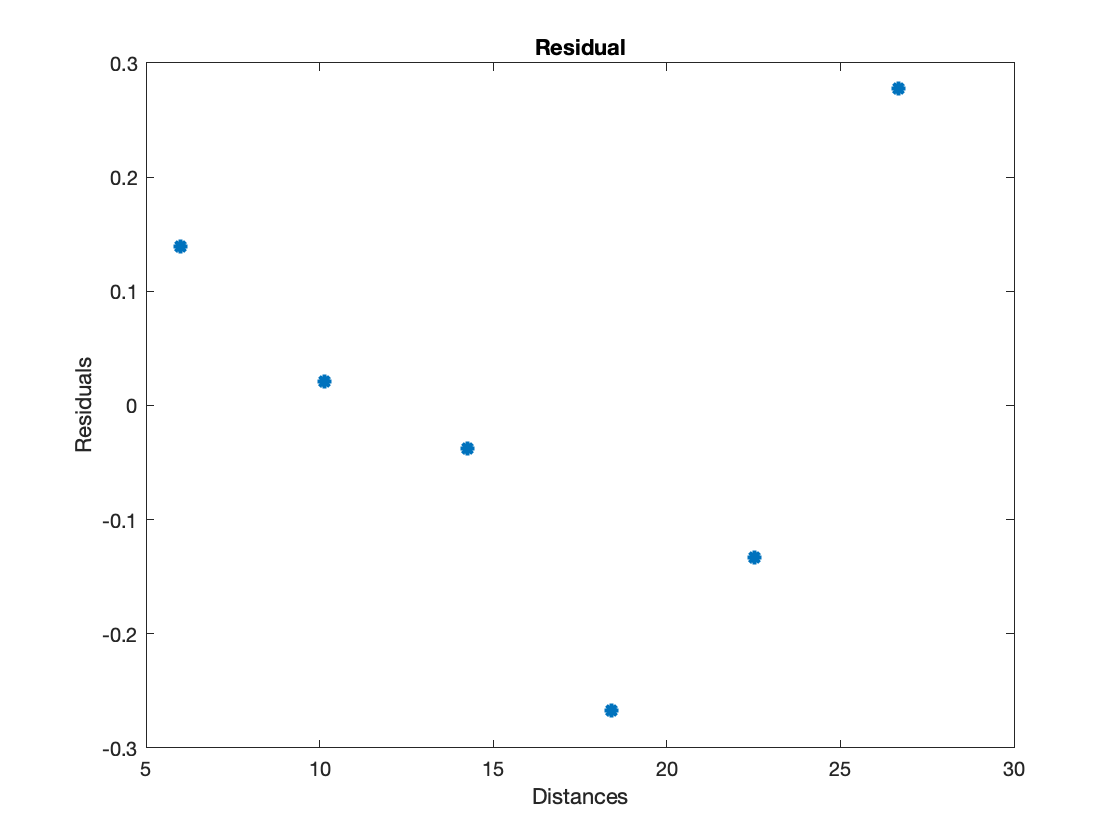

figure(2)
plot(x,r,'*',LineWidth=2)
ylabel('Residuals')
xlabel('Distances')
title('Residual')

## No.2

### Use the standard deviation to form a diagonal weighting matrix

W = (1/sig)*eye(m)

W =     10     0     0     0     0     0
     0    10     0     0     0     0
     0     0    10     0     0     0
     0     0     0    10     0     0
     0     0     0     0    10     0
     0     0     0     0     0    10


### Find the maximum likelihood estimate of the parameters

M_mle = inv(G'*(W^2)*G)*G'*(W^2)*t

M_mle =     2.0323
    0.2203


% Estimate travel times
t_times = zeros(m,1);
for i =1:m
    t_times(i) = M_mle(1) + M_mle(2)*x(i);
end
t_times

t_times =     3.3540
    4.2645
    5.1750
    6.0855
    6.9960
    7.9065


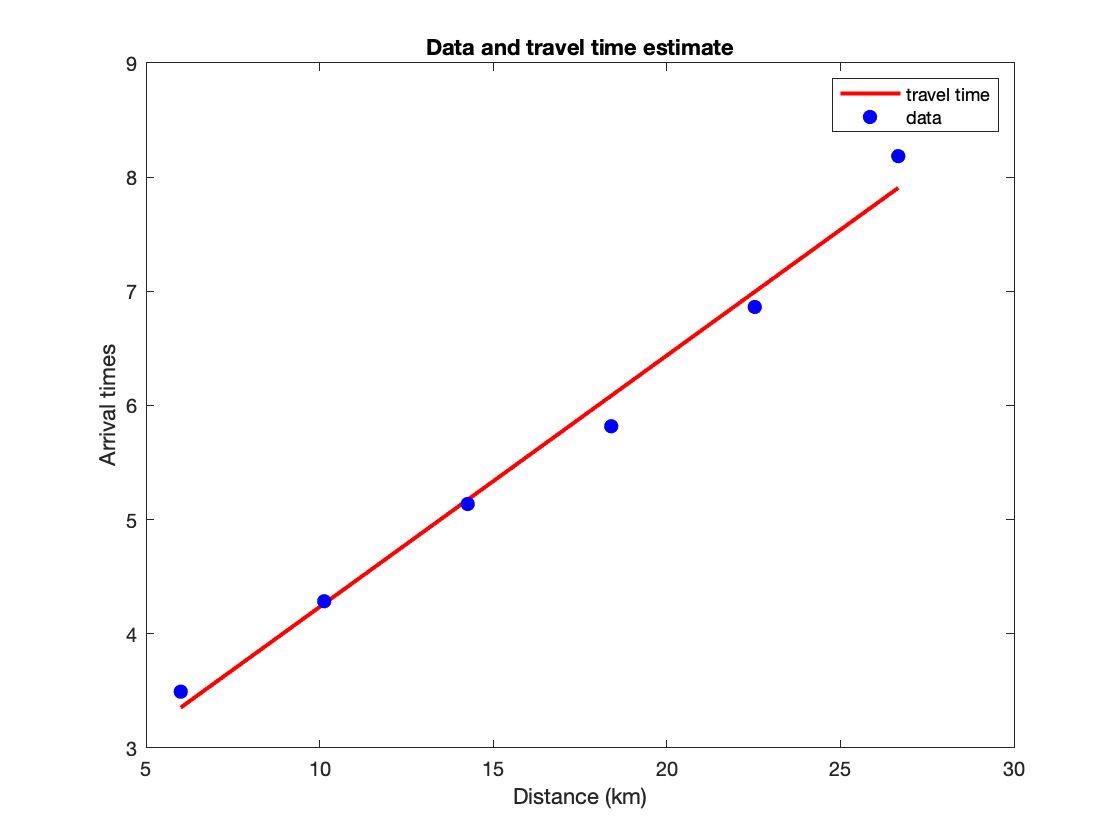

figure(3)
plot(x,t_times,'r',LineWidth=2)
hold on
plot(x,t,'b.','MarkerSize',20)
legend('travel time','data')
ylabel('Arrival times')
xlabel('Distance (km)')
title('Data and travel time estimate')

% residuls
Gm = G*M_mle;
r1 = t - Gm;

figure(4)
plot(x,r1,'*',LineWidth=2)
ylabel('Residuals')
xlabel('Distances')
title('Residual')

### Discuss and explain the difference between the weighted parameter estimates, graphs of their corresponding travel times and residuals, to those you found in 1.

Since the standard deviation ($\sigma$ = 0.1)  is a constant value, this makes the weighted parameter estimates to be equal to the least squares estimates, i.e., $M_{mle} = (G^{T}W^{2}G)^{-1}G^{T}W^{2}t = (G^{T}(\sigma^{-1} I)^{2}G)^{-1}G^{T}(\sigma^{-1} I)^{2}t
 = \sigma^{2}(G^{T}G)^{-1}\sigma^{-2}(G^{T}IG)
= (G^{T}G)^{-1}(G^{T}G) = M_{L2}
$. So getting the equal parameters makes their corresponding travel times and residuals in the two cases to be the same.

## No.3

### Calculate the  chi-square statistic for the data

% using the least squares parameter estimate
chi_lsq = (t-G*M_L2)'*(W^2)*(t - G*M_L2)

chi_lsq = 18.7502

 % using the maximum likelihood parameter
chi_ml = (t-G*M_mle)'*(W^2)*(t - G*M_mle)

chi_ml = 18.7502

### In each case, and simply by inspection, discuss if the value of the $\chi^{2}$ statistic is near the expected value of the $\chi^{2}$ random variable with appropriate degrees of freedom.

Since $M_{mle} = M_{L2}$, this means that in both cases the $\chi^{2}$ statistic is the same which is $\chi^{2} = 18.7502
$. This values is much greater than the expexted value ,$\nu = 4$, of the $\chi^{2}$ random variable with appropriate degrees of freedom, hence the $\chi^{2}$ statistic is not near $\chi^{2}$ random variable and doesn't follow a chi-square distribution. 

## No.4

### Evaluate the p-value for this model. 

m = 6;
n = 2;
p = 1 - chi2cdf(chi_lsq,m-n)

p = 8.7992e-04

### Interpret the p-value. Discuss if this conclusion matches the conclusion you made by inspection in 3.

The p-value is very close to 0, therefore we reject the null hypothesis. This conclusion matches the conclusion made in 3 by inspection, since the p-value being very small and near to zero, means that it exists in the skewed region, which is very far away from the expected value.              